clearvars

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;


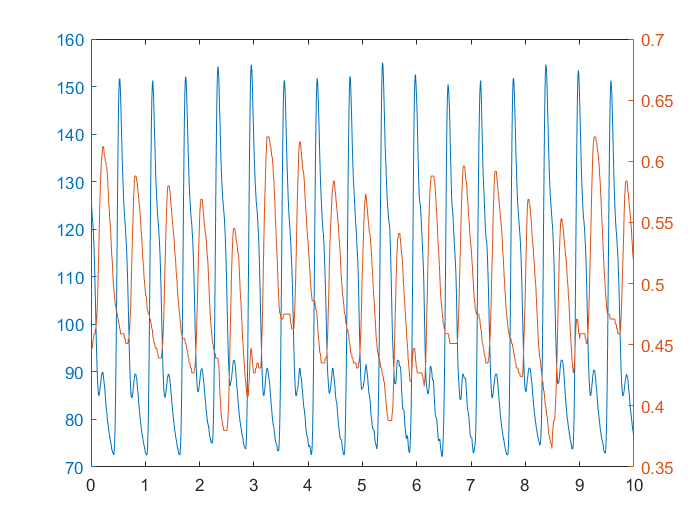


addpath('./FreqFeatures')
data = importdata("../physionet.org/segmented_data/3000063_0016-0011.txt");

figure;
yyaxis left
plot(data(:,1), data(:,2))
hold on;
yyaxis right
plot(data(:,1), data(:,3))
hold off
xlim([0 10])

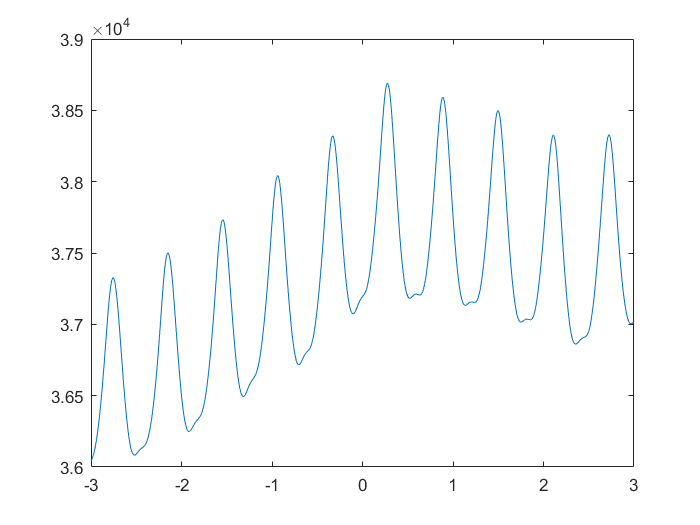


Ts = mean(diff(data(:,1)));

[g, T, deltaT] = crossCorrelation(data(:,1), data(:,2), data(:,3));

figure;
plot(T, g);

deltaT

deltaT = 0.2720


shift = round(deltaT/Ts)

shift = 34

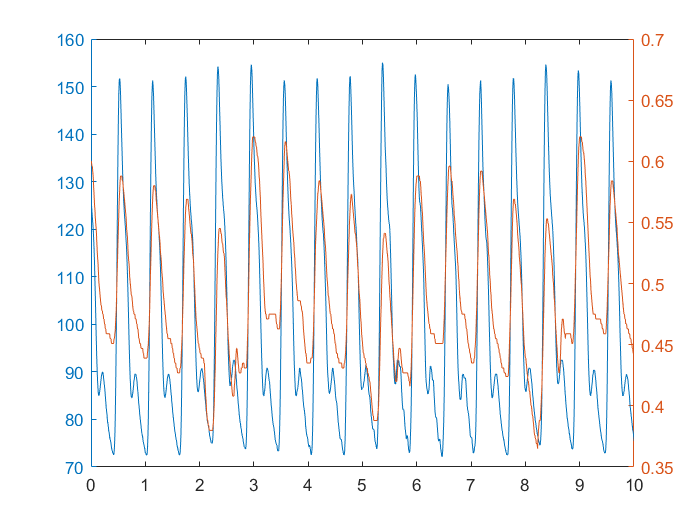


ppg = data(shift:end, 3);
t = data(1:length(ppg), 1);
abp = data(1:length(ppg), 2);

figure;
yyaxis left
plot(t, abp)
hold on;
yyaxis right
plot(t,ppg)
hold off
xlim([0 10])


p = pearsonCoeff(ppg, abp)

p = 0.7758

Removing Out of bounds

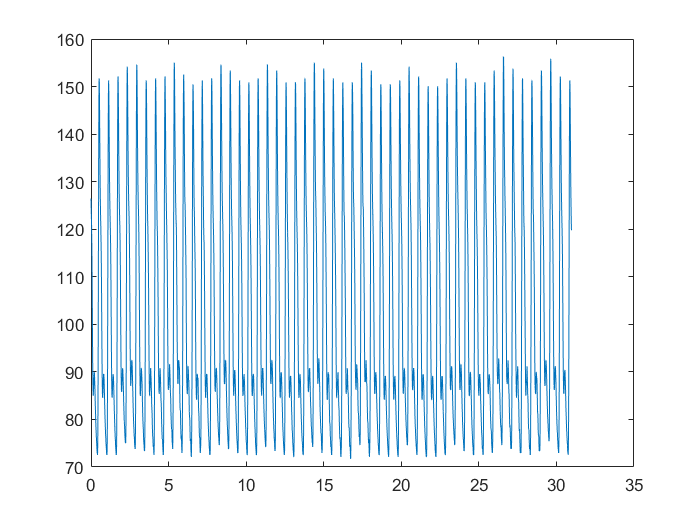


addpath('./FreqFeatures')
data = importdata("../physionet.org/segmented_data/3000063_0016-0011.txt");

figure;
% yyaxis left
plot(data(:,1), data(:,2))

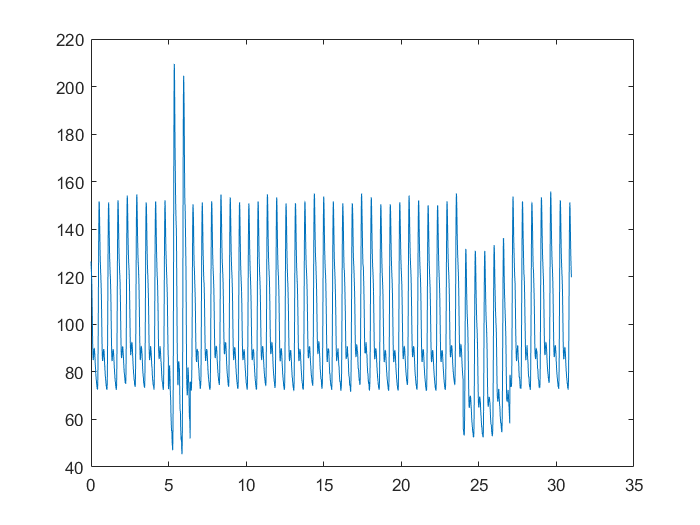

% hold on;
% yyaxis right
% plot(data(:,1), data(:,3))
% hold off

m = mean(data(:,2));
data(625:800,2) = (data(625:800,2)-m)*2 + m;

data(3000:3375,2) = data(3000:3375,2) - 20;

figure;
% yyaxis left
plot(data(:,1), data(:,2))

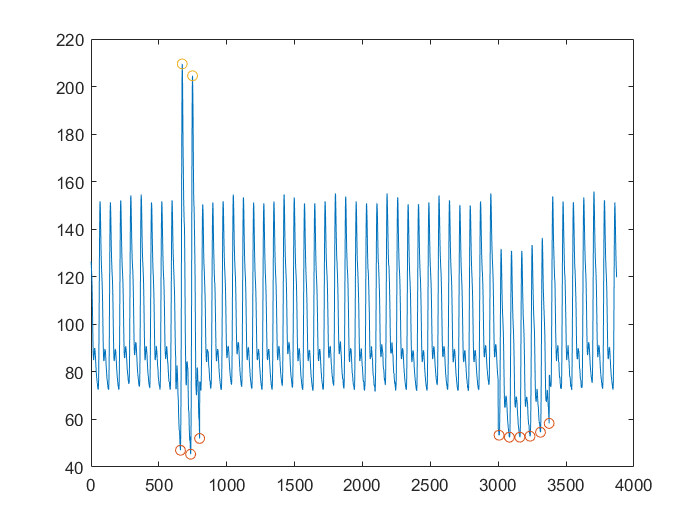


oor = findAbpOutOfRange(data(:,2), [80 180], [60 130], 120);

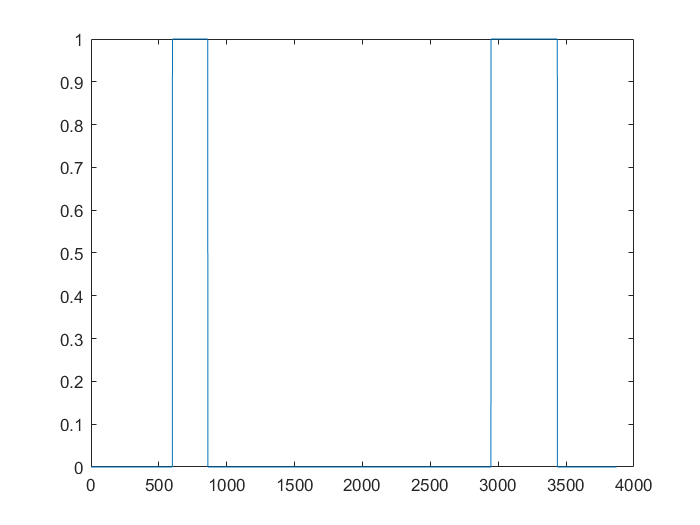


plot(oor);

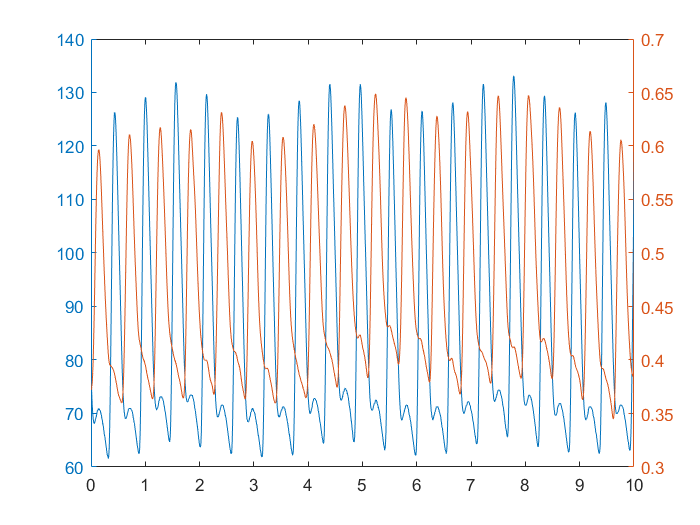

addpath('./FreqFeatures')
data = importdata("../physionet.org/segmented_data/3000063_0011-0029.txt");

figure;
yyaxis left
plot(data(:,1), data(:,2))
hold on;
yyaxis right
plot(data(:,1), data(:,3))
hold off
xlim([0 10])